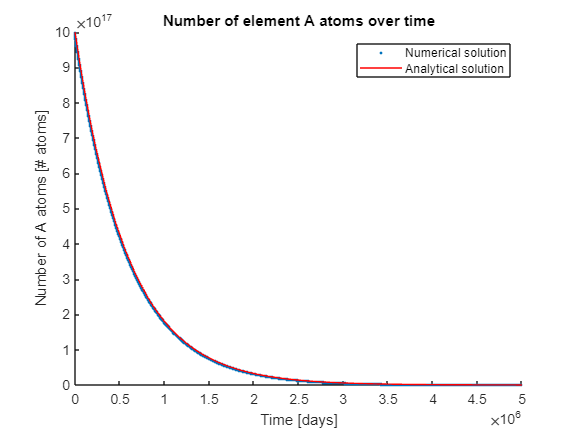

%A script that models the decay of 2 radio active elements into a third
%stable one A->B->C
clear all %clearing crap

syms T %declaring symbolic variables

%initial conditions
A(1) = 1e18;
B(1) = 0;
C(1) = 0;
A0 = A(1);

%decay constants in days
a = 1/(1600*365);
b = 1/3.8;

%timesteps
h = 1; %hop size in days
tf = 1e7; %total number of days to run simulation
t = 1:h:tf; %time sacale in days

%perfoming iterative calculations
for n = 2:1:tf/h

    A(n) = A(n-1) + -1*h*a*A(n-1);
    B(n) = B(n-1) + h*(a*A(n-1) - b*B(n-1));
    C(n) = C(n-1) + h*b*B(n-1);

end

%declaring analytical solutions
Af(T) = A0*exp(-a*T);
Bf(T) = (a*A0/(b-a))*(exp(-1*a*T)-exp(-1*b*T));
Cf(T) = A0 - Af(T) - Bf(T);

%Plotting for emelemnt A
plot(t*h,A,".") %plotting points
hold on
fplot(Af(T),"-r")
hold off
xlim([0 5e6])
ylim([0 1e18])
%beautifying curve
xlabel("Time [days]");
ylabel("Number of A atoms [# atoms]");
title("Number of element A atoms over time")
legend("Numerical solution","Analytical solution")
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

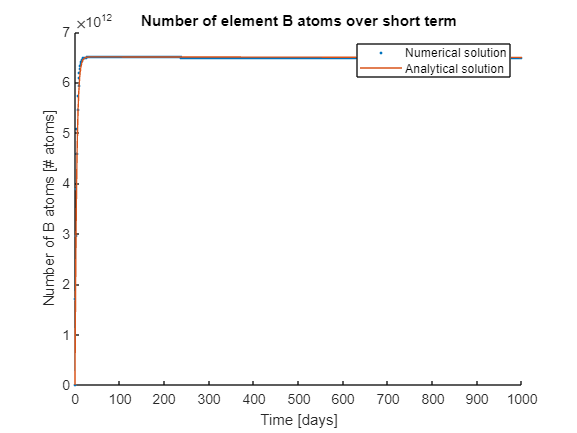


%Plotting for element B in short term
plot(t*h,B,".")
hold on
fplot(Bf(T))
hold off
xlim([0 1000])
%beautifying curve
xlabel("Time [days]");
ylabel("Number of B atoms [# atoms]");
title("Number of element B atoms over short term")
legend("Numerical solution","Analytical solution")
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

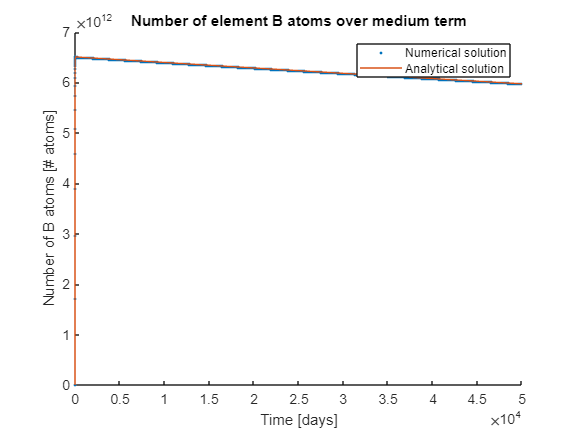


%Plotting for element B in medium term
plot(t*h,B,".")
hold on
fplot(Bf(T))
hold off
xlim([0 5e4])
%beautifying curve
xlabel("Time [days]");
ylabel("Number of B atoms [# atoms]");
title("Number of element B atoms over medium term")
legend("Numerical solution","Analytical solution")
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

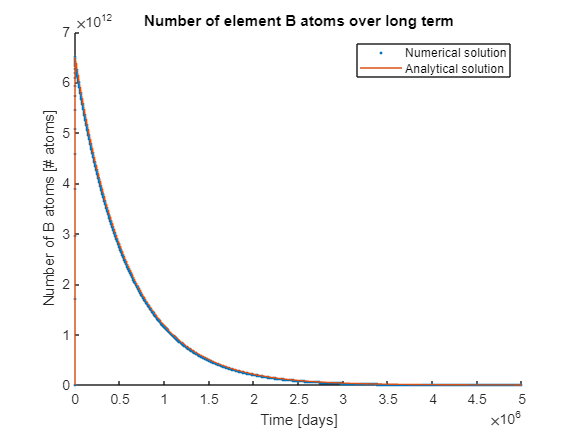


%Plotting for element B in long term
plot(t*h,B,".")
hold on
fplot(Bf(T))
hold off
xlim([0 5e6])
%beautifying curve
xlabel("Time [days]");
ylabel("Number of B atoms [# atoms]");
title("Number of element B atoms over long term")
legend("Numerical solution","Analytical solution")
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

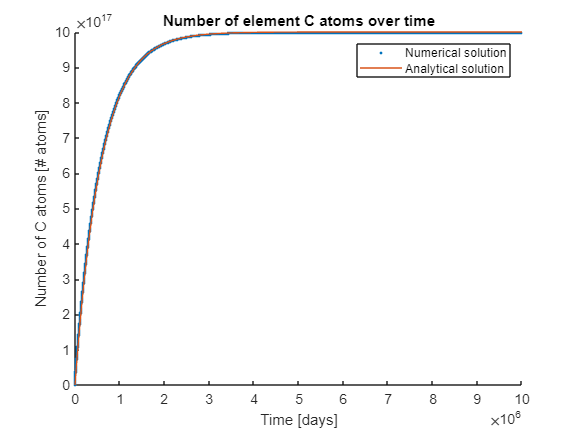


%Plotting for element C in long term
plot(t,C,".")
hold on
fplot(Cf(T))
hold off
xlim([0 1e7])
%beautifying curve
xlabel("Time [days]");
ylabel("Number of C atoms [# atoms]");
title("Number of element C atoms over time")
legend("Numerical solution","Analytical solution")
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;